# `Higher order differential equation and ODE-45 solver`

#### Q1. Solve $\frac{d^2 y}{dx^2 }+\frac{\textrm{dy}}{\textrm{dx}}-6y=0$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=1$and find the value of $y$ at $x=2$ .

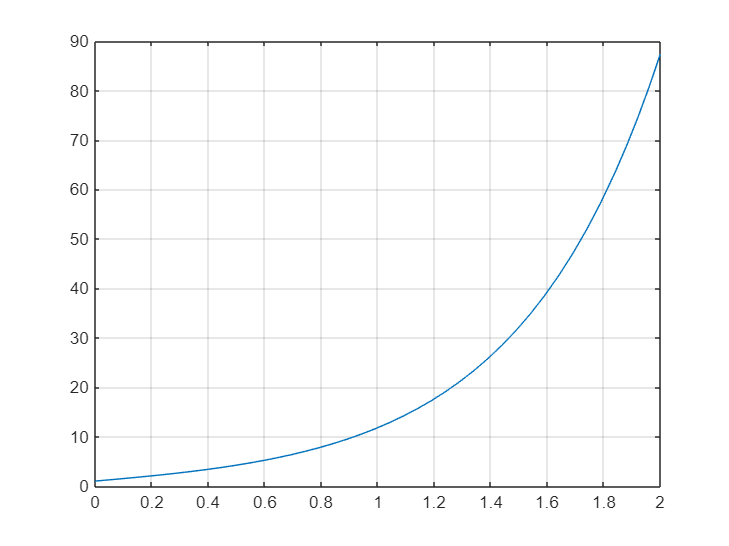

range=[0,2];
ic=[1;1];
[xsol,ysol]=ode45(@orbit,range,ic);
solution=ysol(:,2);
plot(xsol,solution)
grid on

%To find the value of y at x=2
disp("The value of y at x=2 is");

The value of y at x=2 is


disp(solution(end))

   87.3560




function Dydx=orbit(x,Y)
y=Y(1);
z=Y(2);
dydx=z;
dzdx=6*y-z;
Dydx=[dydx;dzdx];
end

#### Q2. Solve $\frac{d^2 y}{dx^2 }-x\frac{\textrm{dy}}{\textrm{dx}}-y=0$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=0$and find the value of $y$ at $x=0\ldotp 2$ .

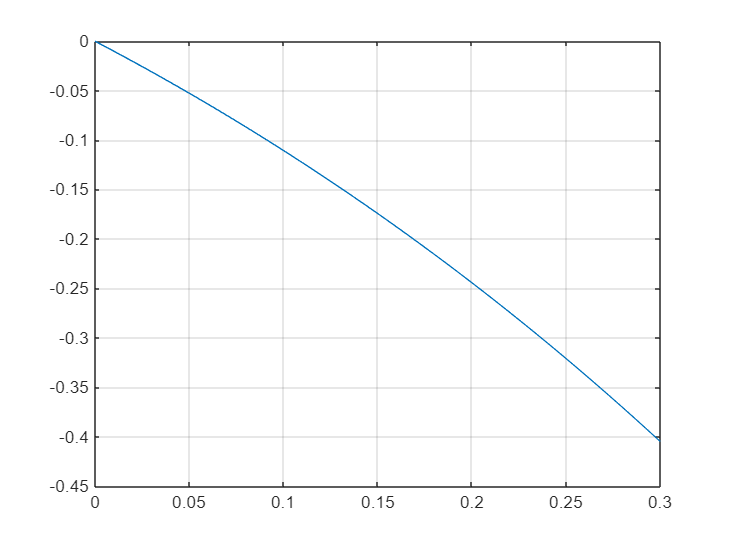

clear
range=[0 0.3];
ic=[1;0];
[xsol,ysol]=ode45(@orbit2,range,ic);
solution=ysol(:,2);
plot(xsol,solution)
grid on

%To find the value of y at x=0.2
disp("The value of y at x=0.2 is");

The value of y at x=0.2 is


disp(solution(end))

   -0.4050



function Dydx=orbit2(x,Y)
y=Y(1);
z=Y(2);
dydx=z;
dzdx=2*z-y;
Dydx=[dydx;dzdx];
end

#### Q3. Solve $\frac{d^2 y}{dx^2 }=2\frac{\textrm{dy}}{\textrm{dx}}-y$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=2$and find the value of $y$ at $x=0\ldotp 1$ .

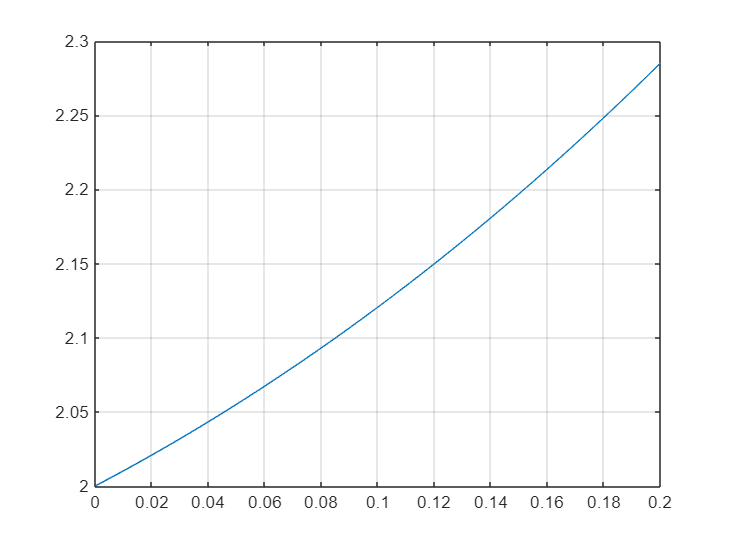

clear
range=[0 0.2];
ic=[1;2];
[xsol,ysol]=ode45(@orbit1,range,ic);
solution=ysol(:,2);
plot(xsol,solution)
grid on

%To find the value of y at x=0.1
disp("the value of y at x=0.1 is")

the value of y at x=0.1 is


disp(solution(end))

    2.2851



function Dydx=orbit1(x,Y)
y=Y(1);
z=Y(2);
dydx=z;
dzdx=y+x*z;
Dydx=[dydx;dzdx];
end

#### Q4. Solve $\frac{d^2 y}{dx^2 }-x{\left(\frac{\textrm{dy}}{\textrm{dx}}\right)}^2 -y^2 =0$ with $y\left(0\right)=1$ and $y^{\prime } \left(0\right)=0$and find the value of $y$ at $x=0\ldotp 2$ .

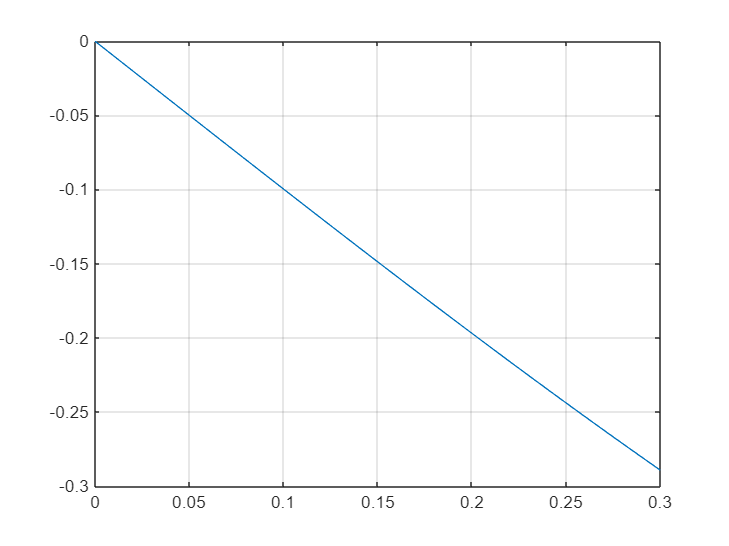

clear
range=[0 0.3];
ic=[1;0];
[xsol,ysol]=ode45(@orbit3,range,ic);
solution=ysol(:,2);
plot(xsol,solution)
grid on

%To find the value of y at x=0.2
disp("the value of y at x=0.2 is")

the value of y at x=0.2 is


disp(solution(end))

   -0.2893



function Dydx=orbit3(x,Y)
y=Y(1);
z=Y(2);
dydx=z;
dzdx=x*z^2-y^2;
Dydx=[dydx;dzdx];
end